# Projection on polytopes

buffer_train = struct with fields:
    X: [22×10000 double]
    Y: [5×10000 double]

buffer_validation = struct with fields:
    X: [22×1000 double]
    Y: [5×1000 double]

Nsamples = 11000

Ninputs = 22

Noutputs = 5

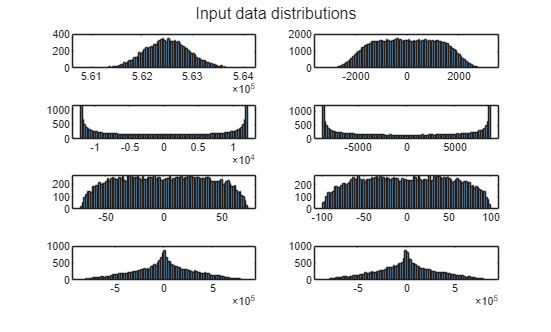

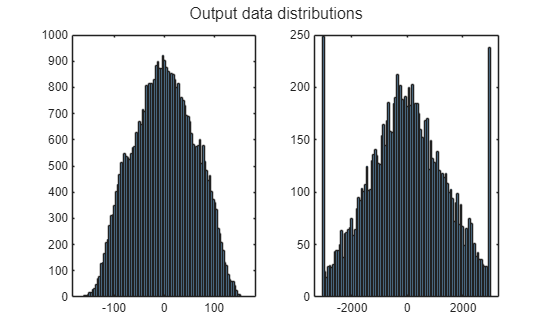

ans = 55.7759

ie_max = 167.1361

ix_max = 71.4286

iy_max = 100

is_max = 114.2857

vo_max = 3000

vB_max = 12000

VCdiff = 0.0020

C = 0.0050

vc_mean_ref = 15000

Xmax = 1.0e+05 *

    5.6250
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.1212
    0.1212
    0.0866
    0.0866
    0.0007


Ymax = 1.0e+03 *

    0.2286
    0.2286
    0.2286
    0.2286
    3.0000


ans =           22       11000


ans =            5       11000


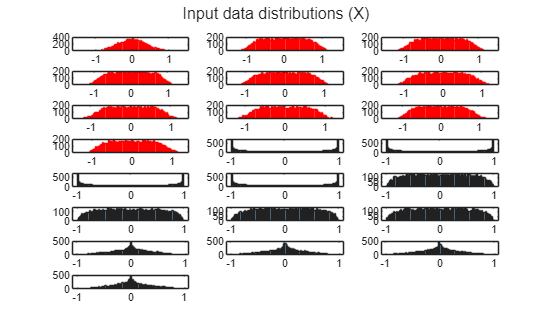

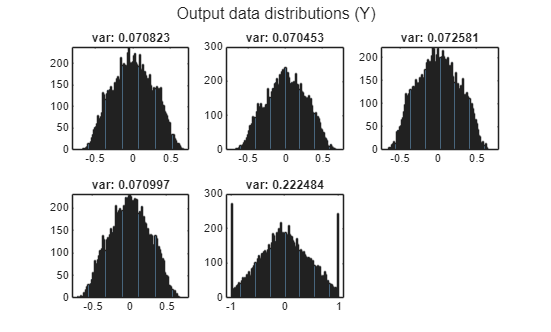

run('DataPreparation.mlx');

# Data

function [ie, iz, is, ixy, iB] = generate_data
    A = [1  1  1  0  0  0  0  0  0;
         0  0  0  1  1  1  0  0  0;
         0  0  0  0  0  0  1  1  1;
        -1  0  0 -1  0  0 -1  0  0;
         0 -1  0  0 -1  0  0 -1  0;
         0  0 -1  0  0 -1  0  0 -1];
    pinvA = pinv(A);
    N     = null(A, 'rational');
    Ax = 7000;
    Ay = 5000;
    [ix_max, iy_max, ~, ~, ~, ~] = max_values(Ax, Ay);

    ie = 300*(2*rand(4, 1)-1);
    iz = N*ie;
    gx = rand * 2*pi;
    ixa = ix_max * sin(gx);
    ixb = ix_max * sin(gx-2*pi/3);
    ixc = ix_max * sin(gx+2*pi/3);
    gy = rand * 2*pi;
    iya = iy_max * sin(gy);
    iyb = iy_max * sin(gy-2*pi/3);
    iyc = iy_max * sin(gy+2*pi/3);
    ixy = [ixa; ixb; ixc; iya; iyb; iyc];
    iB = pinvA * ixy;
    is = iB + iz;
end

[ie, iz, is, ixy, iB] = generate_data

ie =   188.8342
  243.4752
 -223.8079
  248.0255


iz =   456.5270
   34.9737
 -491.5007
 -432.3094
  188.8342
  243.4752
  -24.2176
 -223.8079
  248.0255


is =   419.7571
   50.5782
 -523.1236
 -428.7943
  244.7236
  252.1371
  -48.4841
 -195.7000
  228.9059


ixy =   -52.7883
   68.0664
  -15.2782
   57.5213
  -99.6018
   42.0806


iB =   -36.7699
   15.6045
  -31.6229
    3.5150
   55.8894
    8.6620
  -24.2665
   28.1079
  -19.1196



original = struct();
original.ie = ie;
original.iz = iz;
original.is = is;
original.ixy = ixy;

function compare(original, optimal_projection, projection, name)
    disp(strcat(['Comparation of projection method: ', name]))
    disp('  Original | Optimal | Actual')
    disp('ie')
    disp([original.ie, optimal_projection.ie, projection.ie]);
    % disp('iz')
    % disp([original.iz, optimal_projection.iz, projection.iz]);
    disp('is')
    disp([original.is, optimal_projection.is, projection.is]);
    disp('ixy')
    disp([original.ixy, optimal_projection.ixy, projection.ixy]);
end

# Constraints


$$-\check{i_s}\leq i_B+N\cdot i_\varepsilon\leq\hat{i_s}$$


Define matrices


$$A_c\cdot i_\varepsilon\leq b_c$$


Ac = [N; -N];
bc = [is_max - iB; is_max + iB];
pinvAc = pinv(Ac);

Polytope properties

analyzePolytope(Ac, bc);


=== Polytope Properties ===
Dimensión afín   : 4
Acotado          : Sí
Número de facetas: 18
Número de vértices: 64
Número de aristas : 401
Volumen/Área     : N/A para dimensión >3
Centroide        : [ -7.413 3.713 2.645 -1.075 ]
ChebyCenter      : [ 2.109 22.53 29.89 -19.47 ]
Inradius         : 56.29
Diámetro         : 457.1



Visualize slice

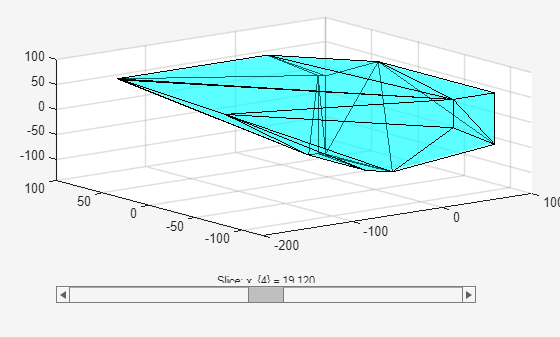

freeDim = 4;
visualizeSlice3D(Ac, bc, freeDim);

## Active set solver

H   = eye(4);
f   = -ie;
options = mpcActiveSetOptions;
[ie_proj, exitflag, iA, lambda] = mpcActiveSetSolver(H, f, Ac, bc, zeros(0, 4), zeros(0, 1), false(18, 1), options);
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

exitflag

exitflag = int32
4


optimal_projection = struct();
optimal_projection.ie = ie_proj;
optimal_projection.iz = iz_proj;
optimal_projection.is = is_proj;
optimal_projection.ixy = ixy_proj;

% Max constraint violation original ie
max(Ac*ie - bc)

ans = 408.8379

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Hardnet-aff

ie_correction = pinvAc * max(0, Ac * ie - bc);
ie_proj = ie - ie_correction;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'HardNet-Aff')

Comparation of projection method: HardNet-Aff
  Original | Optimal | Actual
ie
  188.8342   58.3963  130.5482
  243.4752   39.0562  147.2507
 -223.8079 -142.3936 -162.9303
  248.0255   43.6066  176.6542
is
  419.7571  -38.1044  254.7530
   50.5782   99.6018   47.9866
 -523.1236 -114.2857 -355.5279
 -428.7943  -93.9375 -274.2839
  244.7236  114.2857  186.4376
  252.1371   47.7182  155.9127
  -48.4841   74.5206  -37.9904
 -195.7000 -114.2857 -134.8224
  228.9059   24.4870  157.5346
ixy
  -52.7883  -52.7883  -52.7883
   68.0664   68.0664   68.0664
  -15.2782  -15.2782  -15.2782
   57.5213   57.5213   57.5213
  -99.6018  -99.6018  -99.6018
   42.0806   42.0806   42.0806



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 408.8379

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 241.2422

## Scalar clipping

Ac_ie = Ac * ie;
alpha_i = inf(size(Ac_ie));
pos = Ac_ie > 0;            
alpha_i(pos) = bc(pos) ./ Ac_ie(pos);
alpha = min(1, min(alpha_i));
ie_proj = alpha * ie;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Scalar Clipping')

Comparation of projection method: Scalar Clipping
  Original | Optimal | Actual
ie
  188.8342   58.3963   31.7590
  243.4752   39.0562   40.9487
 -223.8079 -142.3936  -37.6410
  248.0255   43.6066   41.7140
is
  419.7571  -38.1044   40.0109
   50.5782   99.6018   21.4866
 -523.1236 -114.2857 -114.2857
 -428.7943  -93.9375  -69.1927
  244.7236  114.2857   87.6484
  252.1371   47.7182   49.6107
  -48.4841   74.5206  -28.3395
 -195.7000 -114.2857   -9.5331
  228.9059   24.4870   22.5945
ixy
  -52.7883  -52.7883  -52.7883
   68.0664   68.0664   68.0664
  -15.2782  -15.2782  -15.2782
   57.5213   57.5213   57.5213
  -99.6018  -99.6018  -99.6018
   42.0806   42.0806   42.0806



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 408.8379

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 1.4211e-14

## Cimmino original

Mean of constraint violations

K      = 5;         % Number of iterations
lambda = 1.5;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
n2 = sum(Ac.^2, 2); % Precalculate squared norm of each row of Ac
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0) ./ n2;
    d = (Ac.' * V) / size(Ac, 1);
    ie_proj = ie_proj - lambda * d;
end
toc

Elapsed time is 0.004284 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Mean')

Comparation of projection method: Cimmino Mean
  Original | Optimal | Actual
ie
  188.8342   58.3963   99.1025
  243.4752   39.0562  102.4071
 -223.8079 -142.3936 -206.0549
  248.0255   43.6066  147.9019
is
  419.7571  -38.1044  106.5866
   50.5782   99.6018  122.5570
 -523.1236 -114.2857 -281.9319
 -428.7943  -93.9375 -197.9945
  244.7236  114.2857  154.9919
  252.1371   47.7182  111.0690
  -48.4841   74.5206   33.8866
 -195.7000 -114.2857 -177.9471
  228.9059   24.4870  128.7823
ixy
  -52.7883  -52.7883  -52.7883
   68.0664   68.0664   68.0664
  -15.2782  -15.2782  -15.2782
   57.5213   57.5213   57.5213
  -99.6018  -99.6018  -99.6018
   42.0806   42.0806   42.0806



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 408.8379

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 167.6462

## Cimmino modified

Max of constraint violations

K      = 3;         % Number of iterations
lambda = 1;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0);
    [vmax, idx_max] = max(V);
    if vmax <= 0
        break;
    end
    ai    = Ac(idx_max, :)';
    ri    = ai' * ie_proj - bc(idx_max);
    ie_proj = ie_proj - lambda * (ri / (ai' * ai)) * ai;
end
toc

Elapsed time is 0.003792 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Max')

Comparation of projection method: Cimmino Max
  Original | Optimal | Actual
ie
  188.8342   58.3963   58.3963
  243.4752   39.0562   39.0562
 -223.8079 -142.3936 -142.3936
  248.0255   43.6066   43.6066
is
  419.7571  -38.1044  -38.1044
   50.5782   99.6018   99.6018
 -523.1236 -114.2857 -114.2857
 -428.7943  -93.9375  -93.9375
  244.7236  114.2857  114.2857
  252.1371   47.7182   47.7182
  -48.4841   74.5206   74.5206
 -195.7000 -114.2857 -114.2857
  228.9059   24.4870   24.4870
ixy
  -52.7883  -52.7883  -52.7883
   68.0664   68.0664   68.0664
  -15.2782  -15.2782  -15.2782
   57.5213   57.5213   57.5213
  -99.6018  -99.6018  -99.6018
   42.0806   42.0806   42.0806



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 408.8379

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 1.4211e-14

## Dykstra

K        = 1;         % Número de iteraciones externas
lambda   = 1;         % Factor de relajación (p.ej. 1.2)
ie_proj  = ie;        % Inicializa la proyección
n2       = sum(Ac.^2, 2);    % Precalcula ||a_i||^2 para cada restricción
p        = zeros(size(Ac));  % Correcciones acumuladas, una fila por restricción

tic
for k = 1:K
    for i = 1:size(Ac, 1)
        ai  = Ac(i, :).';
        bi  = bc(i);
        aux = ie_proj + p(i, :).';
        ri  = ai.' * aux - bi;
        if ri > 0
            x_new  = aux - lambda * (ri / n2(i)) * ai;
        else
            x_new  = aux;
        end
        p(i,:)    = (aux - x_new).';
        ie_proj   = x_new;
    end
end
toc

Elapsed time is 0.004957 seconds.



iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Dykstra')

Comparation of projection method: Dykstra
  Original | Optimal | Actual
ie
  188.8342   58.3963   58.3963
  243.4752   39.0562   27.4406
 -223.8079 -142.3936 -142.3936
  248.0255   43.6066   55.2222
is
  419.7571  -38.1044  -38.1044
   50.5782   99.6018   99.6018
 -523.1236 -114.2857 -114.2857
 -428.7943  -93.9375  -82.3219
  244.7236  114.2857  114.2857
  252.1371   47.7182   36.1026
  -48.4841   74.5206   62.9050
 -195.7000 -114.2857 -114.2857
  228.9059   24.4870   36.1026
ixy
  -52.7883  -52.7883  -52.7883
   68.0664   68.0664   68.0664
  -15.2782  -15.2782  -15.2782
   57.5213   57.5213   57.5213
  -99.6018  -99.6018  -99.6018
   42.0806   42.0806   42.0806



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 408.8379

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Douglas Peaceman Rachford

K = 3;
lambda = 1;               % relajación (normalmente 1)
ie_proj = ie;                   % estado

tic
for k = 1:K
    x_old = ie_proj;
    % reflejar sucesivamente por cada semiespacio
    for i = 1:size(Ac, 1)
        ai = Ac(i, :).'; bi = bc(i);
        ri = ai.' * ie_proj - bi;
        if ri > 0
            p = ie_proj - (ri / (ai.' * ai)) * ai;
        else
            p = ie_proj;
        end
        r = 2*p - ie_proj;
        ie_proj = ie_proj + lambda * (r - ie_proj);
    end
    % opcional: media con x_old para estabilidad DR
    ie_proj = 0.5*(ie_proj + x_old);
end
toc

Elapsed time is 0.004923 seconds.



iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Douglas Peaceman Rachford')

Comparation of projection method: Douglas Peaceman Rachford
  Original | Optimal | Actual
ie
  188.8342   58.3963   40.1773
  243.4752   39.0562   38.1941
 -223.8079 -142.3936 -138.8585
  248.0255   43.6066   44.4687
is
  419.7571  -38.1044  -52.7883
   50.5782   99.6018  114.2857
 -523.1236 -114.2857 -114.2857
 -428.7943  -93.9375  -74.8564
  244.7236  114.2857   96.0667
  252.1371   47.7182   46.8561
  -48.4841   74.5206   70.1233
 -195.7000 -114.2857 -110.7506
  228.9059   24.4870   25.3491
ixy
  -52.7883  -52.7883  -52.7883
   68.0664   68.0664   68.0664
  -15.2782  -15.2782  -15.2782
   57.5213   57.5213   57.5213
  -99.6018  -99.6018  -99.6018
   42.0806   42.0806   42.0806



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 408.8379

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

# Test projection layer

% Nsamples = 10;
% projLayer = HardNetProjection('cimmino_max', A, N, C, is_max, Xmax, Ymax, 'proj');
% Z = projLayer.predict([Y; X]);
% 
% Y
% Z